## Ejemplo de implementación

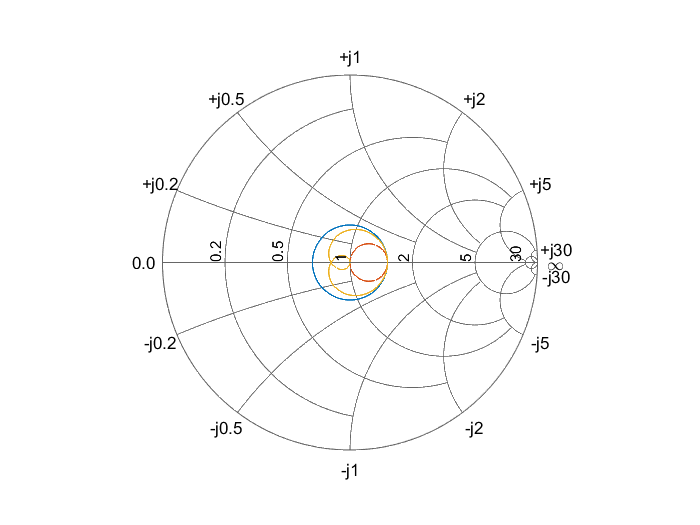

f = 60e6;
Z0 = 50;
ZL = 75;
Z1 = sqrt(Z0*ZL);
f_f0  = 0:1e-3:4;
theta = pi/2*f_f0;

% Impedancia Zin sin adaptar
Zin_0 = Z0*(ZL+1i*Z0*tan(theta)) ./ (Z0+1i*ZL*tan(theta)); GZin_0 = z2gamma(Zin_0);
Zin_1 = Z1*(ZL+1i*Z1*tan(theta)) ./ (Z1+1i*ZL*tan(theta)); GZin_1 = z2gamma(Zin_1); 
Zin_2 = Z0*(Zin_1+1i*Z0*tan(theta)) ./ (Z0+1i*Zin_1.*tan(theta)); GZin_2 = z2gamma(Zin_2); 

figure; % Create a new 
smithplot(GZin_0);
hold on
smithplot(GZin_1);
smithplot(GZin_2);

## Ejercicio 1

#### a) Diseñar un transformador para una carga de 300Ohm, luego graficar la respuesta en frecuencia del  coeficiente de reflexión y hallar un BW para que no supere los -10dB.

Z0 = 50; ZL = 300;

Desarrollo:

Z1 = sqrt(Z0*ZL)

Z1 = 122.4745

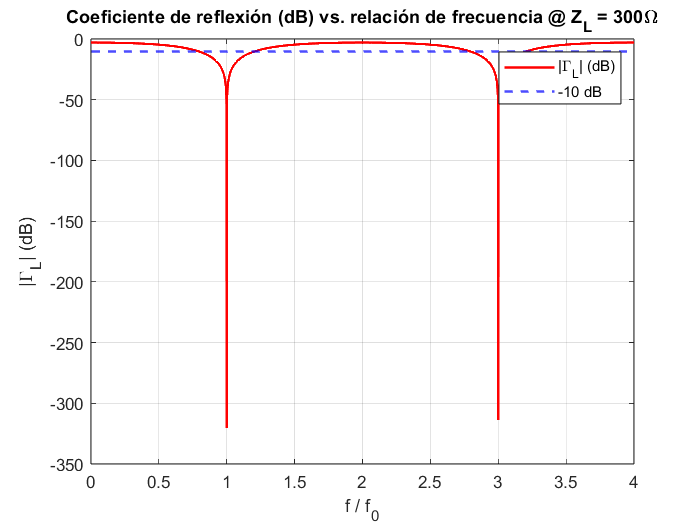

f_f0  = 0:1e-3:4;
theta = pi/2*f_f0;

% Impedancia de entrada sin adaptar 
Zin_0 = Z0*(ZL+1i*Z0*tan(theta)) ./ (Z0+1i*ZL*tan(theta)); GZin_0 = z2gamma(Zin_0);
% Impedancia de entrada al transformador
Zin_1 = Z1*(ZL+1i*Z1*tan(theta)) ./ (Z1+1i*ZL*tan(theta)); GZin_1 = z2gamma(Zin_1); 
% Impedancia de entrada adaptada
Zin_2 = Z0*(Zin_1+1i*Z0*tan(theta)) ./ (Z0+1i*Zin_1.*tan(theta)); GZin_2 = z2gamma(Zin_2); 

% Conversión a dB
GZin_2_dB = 20 * log10(abs(GZin_2));

% Plot
figure;
plot(f_f0, GZin_2_dB, 'r', 'LineWidth', 1.5);
hold on;
yline(-10, 'b--', 'LineWidth', 1.5); % Línea horizontal
xlabel('f / f_0');
ylabel('|\Gamma_L| (dB)');
title('Coeficiente de reflexión (dB) vs. relación de frecuencia @ Z_L = 300\Omega');
grid on;
legend('|\Gamma_L| (dB)', '-10 dB ');
hold off;

Por inspección visual, el BW se encuentra entre $0.7882 < f/f_0 < 1.212 $

#### b) Realizar un transformador para una carga de 125Ohm y comparar BW con el inciso anterior. 

Z0 = 50; ZL = 125;

Desarrollo:

Z1 = sqrt(Z0*ZL)

Z1 = 79.0569

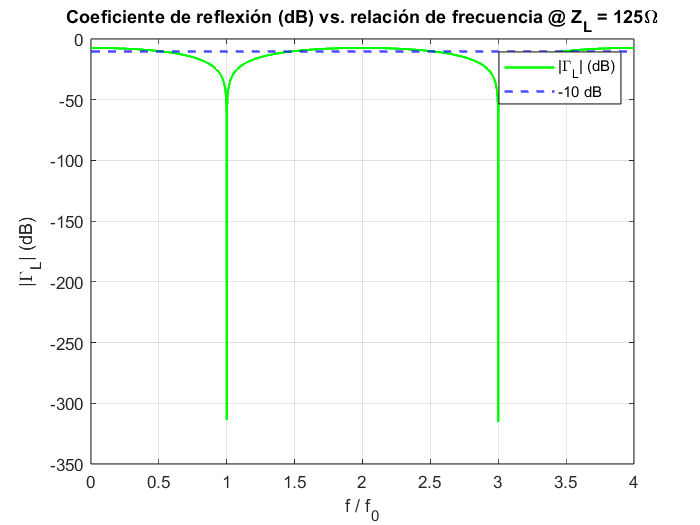

f_f0  = 0:1e-3:4;
theta = pi/2*f_f0;

% Impedancia de entrada sin adaptar 
Zin_0 = Z0*(ZL+1i*Z0*tan(theta)) ./ (Z0+1i*ZL*tan(theta)); GZin_0 = z2gamma(Zin_0);
% Impedancia de entrada al transformador
Zin_1 = Z1*(ZL+1i*Z1*tan(theta)) ./ (Z1+1i*ZL*tan(theta)); GZin_1 = z2gamma(Zin_1); 
% Impedancia de entrada adaptada
Zin_2 = Z0*(Zin_1+1i*Z0*tan(theta)) ./ (Z0+1i*Zin_1.*tan(theta)); GZin_2 = z2gamma(Zin_2); 

% Conversión a dB
GZin_2_dB = 20 * log10(abs(GZin_2));

% Plot
figure;
plot(f_f0, GZin_2_dB, 'g', 'LineWidth', 1.5);
hold on;
yline(-10, 'b--', 'LineWidth', 1.5); % Línea horizontal
xlabel('f / f_0');
ylabel('|\Gamma_L| (dB)');
title('Coeficiente de reflexión (dB) vs. relación de frecuencia @ Z_L = 125\Omega');
grid on;
legend('|\Gamma_L| (dB)', '-10 dB ');
hold off;

Por inspección visual, el BW se encuentra entre $0.504 < f/f_0 < 1.495$. Comparando los resultados, es evidente como, en el primer caso, una carga mayor compromete el ancho de banda del transformador. 

#### c) Implementarlo con linea microstrip

Los parametros del FR4 que se usa son:

f0 = 1e9;

h = 1.5e-3; t = 35e-6; tand = 0.01; sigma = 5.85e7;

epsilon_r = 4.2; % Permitividad efectiva del FR4

c0 = 299792458;
%vp = c0/sqrt(); wl = vp/f0
% Defino rango de frecuencias
freq = 0.5e9:1e6:1.5e9; 

- Resuelvo para Z0 = 50Ohm

Z0 = 50;

% Calculo A
A = (Z0 / 60) * sqrt((epsilon_r + 1) / 2) + ...
    ((epsilon_r - 1) / (epsilon_r + 1)) * (0.23 + (0.11 / epsilon_r));

% Calculo B
B = (377 * pi) / (2 * Z0 * sqrt(epsilon_r));

W_h_case1 = (8 * exp(A)) / (exp(2 * A) - 2);
W_h_case2 = (2 / pi) * (B - 1 - log(2 * B - 1) + ...
             ((epsilon_r - 1) / (2 * epsilon_r)) * (log(B - 1) + 0.39 - (0.61 / epsilon_r)));
 
if W_h_case1 < 2
    W_h = W_h_case1;
else
    W_h = W_h_case2;
end

% Calculo width W
W = W_h * h;

Calculada la anchura para Z0 = 50Ohm instancio la linea de transmision

% No tengo l de Tx, asique asumo l = 0.5*Lambda aproximado
l = 0.5*0.1676;

Tx = rfckt.microstrip('Width', W, 'Height', h, 'Thickness', t, ...
    'EpsilonR', epsilon_r, 'LossTangent', tand, 'LineLength', l, 'SigmaCond', sigma);

% Analicis en el rango de frecuencia
analyze(Tx, freq);

% Impedancia caracteristica en el rango de frecuencias
Z0_real = getz0(Tx); 
disp("Impedancia caracteristica @ 1GHZ"); disp(Z0_real(501))

Impedancia caracteristica @ 1GHZ
   49.7846



- Resuelvo para ZT = 79Ohm

ZT = sqrt(Z0_real(501)*125);

% Calculate A
A = (ZT / 60) * sqrt((epsilon_r + 1) / 2) + ...
    ((epsilon_r - 1) / (epsilon_r + 1)) * (0.23 + (0.11 / epsilon_r));

% Calculate B
B = (377 * pi) / (2 * ZT * sqrt(epsilon_r));

% Calculate W/h for both cases
W_h_case1 = (8 * exp(A)) / (exp(2 * A) - 2);
W_h_case2 = (2 / pi) * (B - 1 - log(2 * B - 1) + ...
             ((epsilon_r - 1) / (2 * epsilon_r)) * (log(B - 1) + 0.39 - (0.61 / epsilon_r)));
    
% Choose the correct W/h based on physical feasibility
if W_h_case1 < 2
    W_h = W_h_case1;
else
    W_h = W_h_case2;
end

WT = W_h*h;
% Calculo permitividad efectiva para el largo de la linea
epsilon_eff = (epsilon_r + 1)/2 + (epsilon_r - 1)/(2 * sqrt(1 + 12 * (h / W))); %WT = 0.001541
% Calculo A 
A = (ZT / 60) * sqrt((epsilon_eff + 1) / 2) + ...
    ((epsilon_eff - 1) / (epsilon_eff + 1)) * (0.23 + (0.11 / epsilon_eff));

% Calculo B
B = (377 * pi) / (2 * ZT * sqrt(epsilon_eff));

W_h_case1 = (8 * exp(A)) / (exp(2 * A) - 2);
W_h_case2 = (2 / pi) * (B - 1 - log(2 * B - 1) + ...
             ((epsilon_eff - 1) / (2 * epsilon_eff)) * (log(B - 1) + 0.39 - (0.61 / epsilon_eff)));
 
if W_h_case1 < 2
    W_h = W_h_case1;
else
    W_h = W_h_case2;
end
% l = lambda/4
l = 0.25*c0/sqrt(epsilon_eff)/f0

l = 0.0419

Trafo = rfckt.microstrip('Width', WT, 'Height', h, 'Thickness', t, ...
    'EpsilonR', epsilon_r, 'LossTangent', tand, 'LineLength', l, 'SigmaCond', sigma);

% Analicis en el rango de frecuencia
analyze(Trafo, freq);

% Impedancia caracteristica en el rango de frecuencias
ZT_real = getz0(Trafo); 
disp('Impedancia ZT en frecuencia central'); disp(ZT_real(501))

Impedancia ZT en frecuencia central
   77.1702



- Instancio la carga ZL = 125Ohm y computo simulacion completa

ZL_real = rfckt.seriesrlc('R',125-50);
analyze(ZL_real,freq);

Combino todos los elementos en casacada

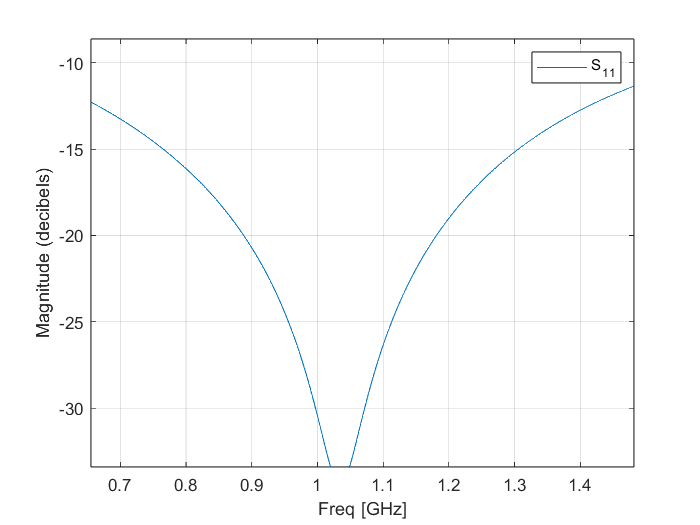

linea_completa = rfckt.cascade('Ckts',{Tx,Trafo,ZL_real});
analyze(linea_completa,freq);

figure; 
plot(linea_completa,'S11','dB');

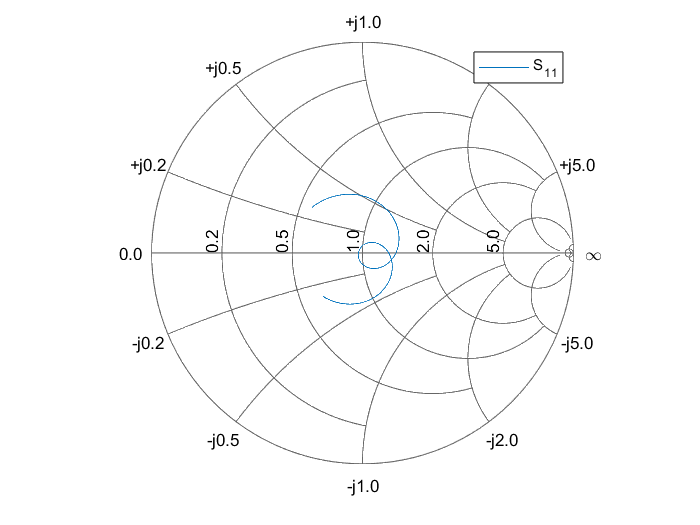

figure;
smith(linea_completa,'S11','dB');